# Forward and Inverse Kinematics

clc
clear
close all
threshold = 1e-10;

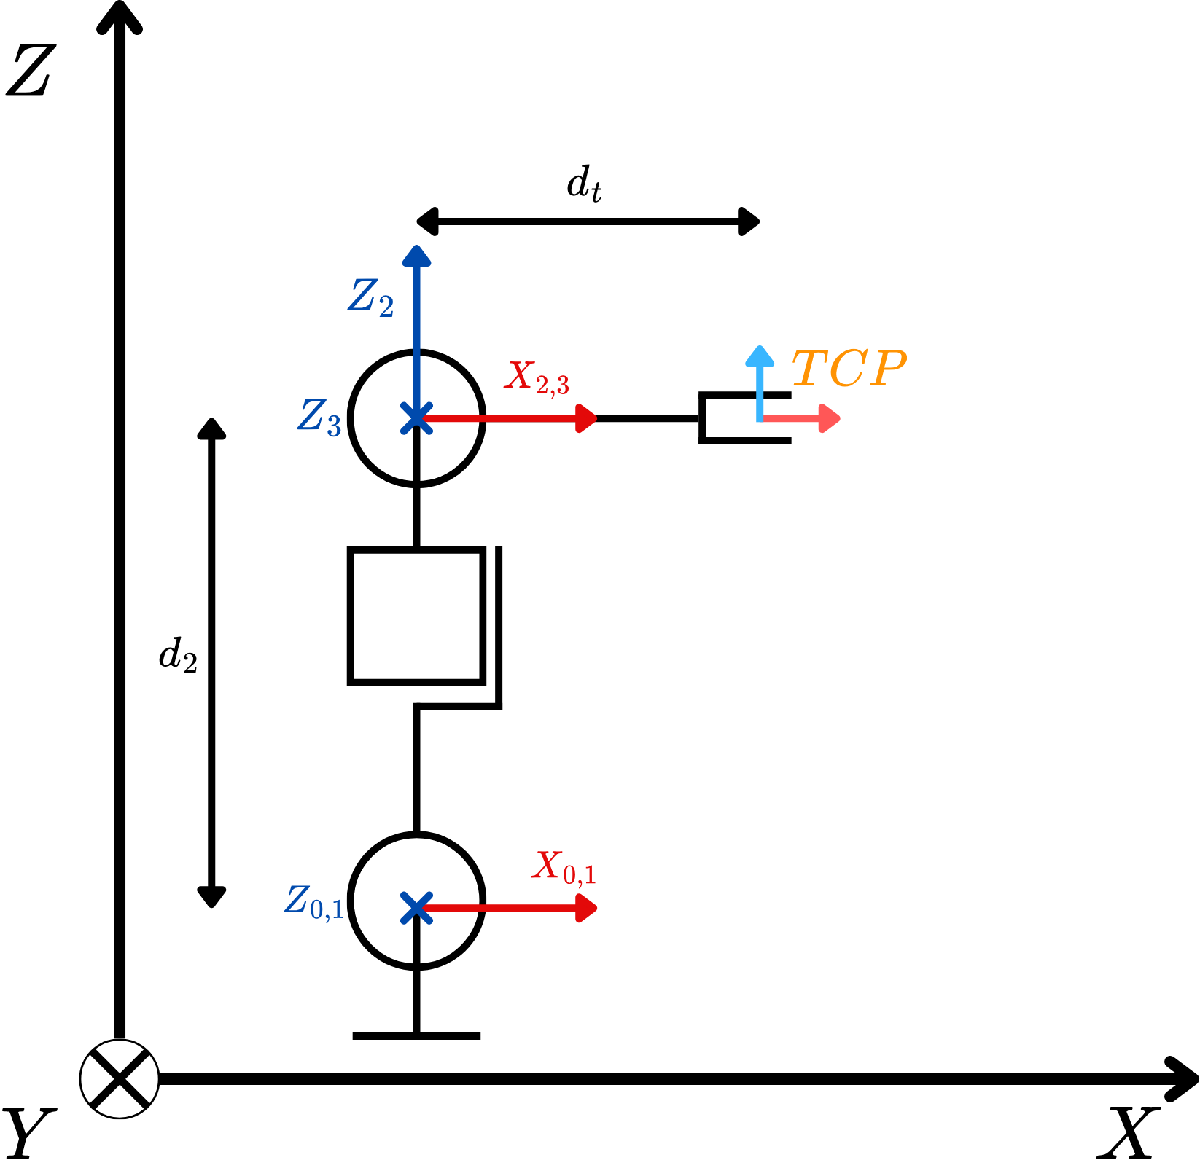

% Define symbolic variables for prismatic and revolute joint displacements
syms d2 dt x z theta r;

% Define the workspace dimensions for visualization
ws = [-50 50 -50 50 0 80] * 10;

% Define plotting options for the robot visualization
plot_options = {'workspace', ws, 'scale', 1, 'view', [30 20], 'tilesize', 2, 'ortho', 'lightpos', [2 2 10]};

% Define the base transformation matrix (homogeneous transformation)
base = [1, 0, 0, 0;
        0, 0, 1, 0;
        0, -1, 0, r;
        0, 0, 0, 1];

% Define the tool transformation matrix (homogeneous transformation)
tool = [1, 0, 0, dt;
        0, 0, -1, 0;
        0, 1, 0, 0;
        0, 0, 0, 1];

% Define the robot links using the SerialLink and Link functions from the Robotics Toolbox
L(1) = Link('revolute', 'alpha', 0, 'a', 0, 'd', 0, 'offset', 0, ...
            'qlim', [deg2rad(-180) deg2rad(180)], 'modified');  % First revolute joint

L(2) = Link('prismatic', 'alpha', pi/2, 'a', 0, 'theta', 0, 'offset', d2, ...
            'qlim', [0 300], 'modified');  % Second prismatic joint

L(3) = Link('revolute', 'alpha', -pi/2, 'a', 0, 'd', 0, 'offset', 0, ...
            'qlim', [deg2rad(-180) deg2rad(180)], 'modified');  % Third revolute joint

% Create the SerialLink object representing the robot
TWR = SerialLink(L, 'name', 'TWR', 'base', base, 'tool', tool, 'plotopt', plot_options)

 
TWR = 
 
TWR (3 axis, RPR, modDH, fastRNE)                                
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|          0|         q2|          0|      1.571|         d2|
|  3|         q3|          0|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base =  1  0   0  0    tool =   1  0  0   dt        
          0          0  0   1  0             0  0  -1  0         
       9.81          0  -1  0  r             0  1  0   0         
                     0  0   0  1             0  0  0   1         
 



% Define symbolic variables for joint angles and displacement
syms theta1 delta2 theta3

% Compute the homogeneous transformation matrices for each joint
MTH_01 = mapSymType(L(1).A(theta1), 'rational', @(x) piecewise(abs(x) <= threshold, 0, x));  % Joint 1 transformation
MTH_12 = mapSymType(L(2).A(delta2), 'rational', @(x) piecewise(abs(x) <= threshold, 0, x));  % Joint 2 transformation
MTH_23 = mapSymType(L(3).A(theta3), 'rational', @(x) piecewise(abs(x) <= threshold, 0, x));  % Joint 3 transformation

% Compute the transformation matrices from the first to the third joint
H_02 = simplify(MTH_01 * MTH_12);  % Base to Joint 2
H_03 = simplify(H_02 * MTH_23)  % Base to Joint 3

$$H\_03 = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{3}\right) & -\sin\left(\theta_{1}+\theta_{3}\right) & 0 & \sin\left(\theta_{1}\right)\,\left(d_{2}+\delta_{2}\right)\\ \sin\left(\theta_{1}+\theta_{3}\right) & \cos\left(\theta_{1}+\theta_{3}\right) & 0 & -\cos\left(\theta_{1}\right)\,\left(d_{2}+\delta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(TWR.base * H_03 * TWR.tool)

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{3}\right) & 0 & \sin\left(\theta_{1}+\theta_{3}\right) & \sin\left(\theta_{1}\right)\,\left(d_{2}+\delta_{2}\right)+\mathrm{dt}\,\cos\left(\theta_{1}+\theta_{3}\right)\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{1}+\theta_{3}\right) & 0 & \cos\left(\theta_{1}+\theta_{3}\right) & r+\cos\left(\theta_{1}\right)\,\left(d_{2}+\delta_{2}\right)-\mathrm{dt}\,\sin\left(\theta_{1}+\theta_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Compute the transformation matrices from the base to each joint
H_B1 = simplify(TWR.base * MTH_01);  % Base to Joint 1
H_B2 = simplify(H_B1 * MTH_12);  % Base to Joint 2
H_B3 = simplify(H_B2 * MTH_23);  % Base to Joint 3

% Compute the final transformation matrix from the base to the tool
H_BT = simplify(H_B3 * TWR.tool)

$$H\_BT = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{3}\right) & 0 & \sin\left(\theta_{1}+\theta_{3}\right) & \sin\left(\theta_{1}\right)\,\left(d_{2}+\delta_{2}\right)+\mathrm{dt}\,\cos\left(\theta_{1}+\theta_{3}\right)\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{1}+\theta_{3}\right) & 0 & \cos\left(\theta_{1}+\theta_{3}\right) & r+\cos\left(\theta_{1}\right)\,\left(d_{2}+\delta_{2}\right)-\mathrm{dt}\,\sin\left(\theta_{1}+\theta_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Define equations
eqx = H_BT(1,4) == x;
eqz = H_BT(3,4) == z;
eqth = theta1+theta3 == theta;
ik = [eqx eqz eqth];

S=solve(ik,[delta2 theta1 theta3])

S = struct with fields:
    delta2: [2×1 sym]
    theta1: [2×1 sym]
    theta3: [2×1 sym]


simplify(S.delta2)

$$ans = \begin{array}{l} \left(\begin{array}{c} -d_{2}-\sigma_{1}\\ \sigma_{1}-d_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\left(\cos\left(\theta \right)+1\right)\,\sqrt{\frac{{\mathrm{dt}}^{2}-2\,\sin\left(\theta \right)\,\mathrm{dt}\,r-2\,\cos\left(\theta \right)\,\mathrm{dt}\,x+2\,\sin\left(\theta \right)\,\mathrm{dt}\,z+r^{2}-2\,r\,z+x^{2}+z^{2}}{{\cos\left(\frac{\theta }{2}\right)}^{4}}}}{2} \end{array}$$

simplify(S.theta1)

$$ans = \begin{array}{l} \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{z-r+\sigma_{1}+\mathrm{dt}\,\sin\left(\theta \right)}{x-\mathrm{dt}\,\cos\left(\theta \right)}\right)\\ 2\,\mathrm{atan}\left(\frac{r-z+\sigma_{1}-\mathrm{dt}\,\sin\left(\theta \right)}{x-\mathrm{dt}\,\cos\left(\theta \right)}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\left(\cos\left(\theta \right)+1\right)\,\sqrt{\frac{{\mathrm{dt}}^{2}-2\,\sin\left(\theta \right)\,\mathrm{dt}\,r-2\,\cos\left(\theta \right)\,\mathrm{dt}\,x+2\,\sin\left(\theta \right)\,\mathrm{dt}\,z+r^{2}-2\,r\,z+x^{2}+z^{2}}{{\cos\left(\frac{\theta }{2}\right)}^{4}}}}{2} \end{array}$$

simplify(S.theta3)

$$ans = \begin{array}{l} \left(\begin{array}{c} \theta +2\,\mathrm{atan}\left(\frac{z-r+\sigma_{1}+\mathrm{dt}\,\sin\left(\theta \right)}{x-\mathrm{dt}\,\cos\left(\theta \right)}\right)\\ \theta -2\,\mathrm{atan}\left(\frac{r-z+\sigma_{1}-\mathrm{dt}\,\sin\left(\theta \right)}{x-\mathrm{dt}\,\cos\left(\theta \right)}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\left(\cos\left(\theta \right)+1\right)\,\sqrt{\frac{{\mathrm{dt}}^{2}-2\,\sin\left(\theta \right)\,\mathrm{dt}\,r-2\,\cos\left(\theta \right)\,\mathrm{dt}\,x+2\,\sin\left(\theta \right)\,\mathrm{dt}\,z+r^{2}-2\,r\,z+x^{2}+z^{2}}{{\cos\left(\frac{\theta }{2}\right)}^{4}}}}{2} \end{array}$$

% q = [0 0 0];
% d2=396.5;
% dt=220;
% TWR.links(1,2).offset=d2;
% TWR.tool=[1, 0, 0, dt;
%         0, 0, -1, 0;
%         0, 1, 0, 0;
%         0, 0, 0, 1];
% T=TWR.fkine(q)
% TWR.ikine(T)
% TWR.teach(q)

H_01 = HT("r", 0, 0, theta1, 0, 0);
H_01 = mapSymType(H_01, 'rational', @(x) piecewise(abs(x) <= threshold, 0, x));
H_12 = HT("p", pi/2, 0, 0, delta2, d2);
H_12 = mapSymType(H_12, 'rational', @(x) piecewise(abs(x) <= threshold, 0, x))

$$H\_12 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & -1 & -d_{2}-\delta_{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_23 = HT("r", -pi/2, 0, theta3, 0, 0);
H_23 = mapSymType(H_23, 'rational', @(x) piecewise(abs(x) <= threshold, 0, x));

% Compute the transformation matrices from the base to each joint
H_B1 = simplify(base * H_01);  % Base to Joint 1
H_B2 = simplify(H_B1 * H_12);  % Base to Joint 2
H_B3 = simplify(H_B2 * H_23);  % Base to Joint 3

% Compute the final transformation matrix from the base to the tool
H_BT = simplify(H_B3 * tool)

$$H\_BT = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{3}\right) & 0 & \sin\left(\theta_{1}+\theta_{3}\right) & \sin\left(\theta_{1}\right)\,\left(d_{2}+\delta_{2}\right)+\mathrm{dt}\,\cos\left(\theta_{1}+\theta_{3}\right)\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{1}+\theta_{3}\right) & 0 & \cos\left(\theta_{1}+\theta_{3}\right) & r+\cos\left(\theta_{1}\right)\,\left(d_{2}+\delta_{2}\right)-\mathrm{dt}\,\sin\left(\theta_{1}+\theta_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


function H=HT(type, alpha, a, theta, d, offset)
    if strcmp(type, "r")        
        theta = theta+offset;    
    elseif strcmp(type, "p")
        d = d+offset;
    end
    H = [rotx(alpha),zeros(3,1);[0 0 0 1]]*[eye(3),[a; 0; 0];[0 0 0 1]]*[rotz(theta),zeros(3,1);[0 0 0 1]]*[eye(3),[0; 0; d];[0 0 0 1]];
end

# CoG

% clc
% clear
% close all

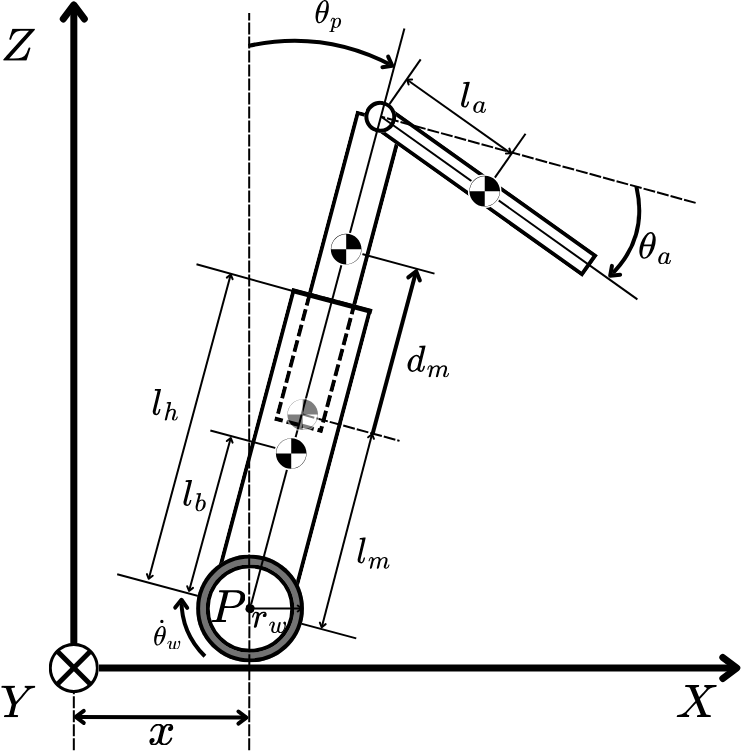

% Define symbolic variables for link lengths, masses, and other parameters
syms lbz lbx lm lh la mw mb mm ma z th_t lt
% Define the rotation matrix for the first joint (theta1)
Rp = simplify([cos(pi/2 - theta1), -sin(pi/2 - theta1);
               sin(pi/2 - theta1),  cos(pi/2 - theta1)]);

% Define the rotation matrix for the third joint (theta3)
Ra = [cos(-theta3), -sin(-theta3);
      sin(-theta3),  cos(-theta3)];

% Compute the center of mass positions for each link
Gb = Rp * [lbz; lbx]  % Center of mass of the base

$$Gb = \left(\begin{array}{c} \mathrm{lbz}\,\sin\left(\theta_{1}\right)-\mathrm{lbx}\,\cos\left(\theta_{1}\right)\\ \mathrm{lbz}\,\cos\left(\theta_{1}\right)+\mathrm{lbx}\,\sin\left(\theta_{1}\right) \end{array}\right)$$

Gm = Rp * [lm + delta2; 0]  % Center of mass of the middle link

$$Gm = \left(\begin{array}{c} \sin\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)\\ \cos\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right) \end{array}\right)$$


% Compute the rotated position of the arm's center of mass
GaR = simplify(expand(Rp * ([lh + delta2; 0] + Ra * [0; -la])))

$$GaR = \left(\begin{array}{c} \mathrm{la}\,\cos\left(\theta_{1}+\theta_{3}\right)+\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)\\ \delta_{2}\,\cos\left(\theta_{1}\right)-\mathrm{la}\,\sin\left(\theta_{1}+\theta_{3}\right)+\mathrm{lh}\,\cos\left(\theta_{1}\right) \end{array}\right)$$


% Compute the overall center of gravity of the robot
CoG = simplify((mb * Gb + mm * Gm + ma * GaR) / (mb + mm + ma))

$$CoG = \left(\begin{array}{c} \frac{\mathrm{ma}\,\left(\mathrm{la}\,\cos\left(\theta_{1}+\theta_{3}\right)+\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)\right)-\mathrm{mb}\,\left(\mathrm{lbx}\,\cos\left(\theta_{1}\right)-\mathrm{lbz}\,\sin\left(\theta_{1}\right)\right)+\mathrm{mm}\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{mm}}\\ \frac{\mathrm{mb}\,\left(\mathrm{lbz}\,\cos\left(\theta_{1}\right)+\mathrm{lbx}\,\sin\left(\theta_{1}\right)\right)+\mathrm{ma}\,\left(\delta_{2}\,\cos\left(\theta_{1}\right)-\mathrm{la}\,\sin\left(\theta_{1}+\theta_{3}\right)+\mathrm{lh}\,\cos\left(\theta_{1}\right)\right)+\mathrm{mm}\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{mm}} \end{array}\right)$$


% Assume the fork paralell to the floor
CoG = subs(CoG,theta1+theta3,0)

$$CoG = \left(\begin{array}{c} \frac{\mathrm{ma}\,\left(\mathrm{la}+\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)\right)-\mathrm{mb}\,\left(\mathrm{lbx}\,\cos\left(\theta_{1}\right)-\mathrm{lbz}\,\sin\left(\theta_{1}\right)\right)+\mathrm{mm}\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{mm}}\\ \frac{\mathrm{ma}\,\left(\delta_{2}\,\cos\left(\theta_{1}\right)+\mathrm{lh}\,\cos\left(\theta_{1}\right)\right)+\mathrm{mb}\,\left(\mathrm{lbz}\,\cos\left(\theta_{1}\right)+\mathrm{lbx}\,\sin\left(\theta_{1}\right)\right)+\mathrm{mm}\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{mm}} \end{array}\right)$$


cog_eq1 = tan(th_t) == CoG(1)/CoG(2)

$$cog\_eq1 = \tan\left({\mathrm{th}}_{t}\right)=\frac{\mathrm{ma}\,\left(\mathrm{la}+\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)\right)+\mathrm{lb}\,\mathrm{mb}\,\sin\left(\theta_{1}\right)+\mathrm{mm}\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}\,\left(\delta_{2}\,\cos\left(\theta_{1}\right)+\mathrm{lh}\,\cos\left(\theta_{1}\right)\right)+\mathrm{lb}\,\mathrm{mb}\,\cos\left(\theta_{1}\right)+\mathrm{mm}\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}$$

cog_eq2 = lt^2 == CoG.'*CoG

$$cog\_eq2 = \begin{array}{l} {\mathrm{lt}}^{2}=\frac{{\left(\mathrm{ma}\,\left(\mathrm{la}+\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)\right)+\mathrm{lb}\,\mathrm{mb}\,\sin\left(\theta_{1}\right)+\mathrm{mm}\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)\right)}^{2}}{\sigma_{1}}+\frac{{\left(\mathrm{ma}\,\left(\delta_{2}\,\cos\left(\theta_{1}\right)+\mathrm{lh}\,\cos\left(\theta_{1}\right)\right)+\mathrm{lb}\,\mathrm{mb}\,\cos\left(\theta_{1}\right)+\mathrm{mm}\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)\right)}^{2}}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}={\left(\mathrm{ma}+\mathrm{mb}+\mathrm{mm}\right)}^{2} \end{array}$$

cog_eqs = [cog_eq1; cog_eq2]

$$cog\_eqs = \begin{array}{l} \left(\begin{array}{c} \tan\left({\mathrm{th}}_{t}\right)=\frac{\sigma_{1}}{\sigma_{2}}\\ {\mathrm{lt}}^{2}=\frac{{\sigma_{1}}^{2}}{{\left(\mathrm{ma}+\mathrm{mb}+\mathrm{mm}\right)}^{2}}+\frac{{\sigma_{2}}^{2}}{{\left(\mathrm{ma}+\mathrm{mb}+\mathrm{mm}\right)}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{ma}\,\left(\mathrm{la}+\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)\right)+\mathrm{lb}\,\mathrm{mb}\,\sin\left(\theta_{1}\right)+\mathrm{mm}\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)\\ \sigma_{2}=\mathrm{ma}\,\left(\delta_{2}\,\cos\left(\theta_{1}\right)+\mathrm{lh}\,\cos\left(\theta_{1}\right)\right)+\mathrm{lb}\,\mathrm{mb}\,\cos\left(\theta_{1}\right)+\mathrm{mm}\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right) \end{array}$$

S = solve(cog_eqs,[delta2 theta1])

S = struct with fields:
    delta2: -(2*la*lh*ma^2 + la^2*ma^2*tan(th_t)^3 - lt^2*ma^2*tan(th_t)^3 - lt^2*mb^2*tan(th_t)^3 - lt^2*mm^2*tan(th_t)^3 + 3*la^2*ma^2*root(2*lt^2*mb*mm*z^4*tan(th_t)^2 + 2*lt^2*ma*mm*z^4*tan(th_t)^2 + 2*lt^2*ma*mb*z^4*tan(th_t)^2 + lt^2*mm^2*z^4*ta…
    theta1: 2*atan(root(2*lt^2*mb*mm*z^4*tan(th_t)^2 + 2*lt^2*ma*mm*z^4*tan(th_t)^2 + 2*lt^2*ma*mb*z^4*tan(th_t)^2 + lt^2*mm^2*z^4*tan(th_t)^2 + lt^2*mb^2*z^4*tan(th_t)^2 + lt^2*ma^2*z^4*tan(th_t)^2 - la^2*ma^2*z^4*tan(th_t)^2 - la^2*ma^2*z^4 + 8*lt^2…



H_BT = subs(H_BT,theta1+theta3,0);

% Define equations
eqn1 = simplify(CoG(1)) == 0;
eqn2 = H_BT(3,4) == z;
eqns = [eqn1; eqn2]

$$eqns = \left(\begin{array}{c} \frac{\mathrm{ma}\,\left(\mathrm{la}+\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)\right)+\mathrm{lb}\,\mathrm{mb}\,\sin\left(\theta_{1}\right)+\mathrm{mm}\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{mm}}=0\\ r+\cos\left(\theta_{1}\right)\,\left(d_{2}+\delta_{2}\right)=z \end{array}\right)$$

S = solve(eqns,[delta2 theta1])

S = struct with fields:
    delta2: -(2*d2*ma + 2*d2*mm + 2*ma*r + 2*mm*r - 2*ma*z - 2*mm*z + la*ma*root(z1^4 + (2*z1^3*(- d2*ma - d2*mm + lb*mb + lh*ma + lm*mm + ma*r + mm*r - ma*z - mm*z))/(la*ma) - (2*z1*(- d2*ma - d2*mm + lb*mb + lh*ma + lm*mm - ma*r - mm*r + ma*z + mm*z…
    theta1: 2*atan(root(z1^4 + (2*z1^3*(- d2*ma - d2*mm + lb*mb + lh*ma + lm*mm + ma*r + mm*r - ma*z - mm*z))/(la*ma) - (2*z1*(- d2*ma - d2*mm + lb*mb + lh*ma + lm*mm - ma*r - mm*r + ma*z + mm*z))/(la*ma) - 1, z1, 1))


S.delta2

$$ans = \begin{array}{l} -\frac{2\,d_{2}\,\mathrm{ma}+2\,d_{2}\,\mathrm{mm}+2\,\mathrm{ma}\,r+2\,\mathrm{mm}\,r-2\,\mathrm{ma}\,z-2\,\mathrm{mm}\,z+\mathrm{la}\,\mathrm{ma}\,\sigma_{1}-2\,d_{2}\,\mathrm{ma}\,{\sigma_{1}}^{2}-2\,d_{2}\,\mathrm{mm}\,{\sigma_{1}}^{2}+\mathrm{la}\,\mathrm{ma}\,{\sigma_{1}}^{3}+2\,\mathrm{lb}\,\mathrm{mb}\,{\sigma_{1}}^{2}+2\,\mathrm{lh}\,\mathrm{ma}\,{\sigma_{1}}^{2}+2\,\mathrm{lm}\,\mathrm{mm}\,{\sigma_{1}}^{2}+2\,\mathrm{ma}\,r\,{\sigma_{1}}^{2}+2\,\mathrm{mm}\,r\,{\sigma_{1}}^{2}-2\,\mathrm{ma}\,z\,{\sigma_{1}}^{2}-2\,\mathrm{mm}\,z\,{\sigma_{1}}^{2}}{2\,\left(\mathrm{ma}+\mathrm{mm}\right)}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{root}\left({z_{1}}^{4}+\frac{2\,{z_{1}}^{3}\,\left(-d_{2}\,\mathrm{ma}-d_{2}\,\mathrm{mm}+\mathrm{lb}\,\mathrm{mb}+\mathrm{lh}\,\mathrm{ma}+\mathrm{lm}\,\mathrm{mm}+\mathrm{ma}\,r+\mathrm{mm}\,r-\mathrm{ma}\,z-\mathrm{mm}\,z\right)}{\mathrm{la}\,\mathrm{ma}}-\frac{2\,z_{1}\,\left(-d_{2}\,\mathrm{ma}-d_{2}\,\mathrm{mm}+\mathrm{lb}\,\mathrm{mb}+\mathrm{lh}\,\mathrm{ma}+\mathrm{lm}\,\mathrm{mm}-\mathrm{ma}\,r-\mathrm{mm}\,r+\mathrm{ma}\,z+\mathrm{mm}\,z\right)}{\mathrm{la}\,\mathrm{ma}}-1,z_{1},1\right) \end{array}$$

S.theta1

$$ans = 2\,\mathrm{atan}\left(\mathrm{root}\left({z_{1}}^{4}+\frac{2\,{z_{1}}^{3}\,\left(-d_{2}\,\mathrm{ma}-d_{2}\,\mathrm{mm}+\mathrm{lb}\,\mathrm{mb}+\mathrm{lh}\,\mathrm{ma}+\mathrm{lm}\,\mathrm{mm}+\mathrm{ma}\,r+\mathrm{mm}\,r-\mathrm{ma}\,z-\mathrm{mm}\,z\right)}{\mathrm{la}\,\mathrm{ma}}-\frac{2\,z_{1}\,\left(-d_{2}\,\mathrm{ma}-d_{2}\,\mathrm{mm}+\mathrm{lb}\,\mathrm{mb}+\mathrm{lh}\,\mathrm{ma}+\mathrm{lm}\,\mathrm{mm}-\mathrm{ma}\,r-\mathrm{mm}\,r+\mathrm{ma}\,z+\mathrm{mm}\,z\right)}{\mathrm{la}\,\mathrm{ma}}-1,z_{1},1\right)\right)$$

# Numerical solution CoG

%--- Real robot---
% Define numerical values for d2 and dt (prismatic displacement and tool length)
r_num = 75;
d2_num = 397.5;
dt_num = 220;
[mb_num, mm_num, ma_num] = struct('k', num2cell([43.1, 21.5, 3.5])).k;
[lb_num, lh_num, lm_num, la_num] = struct('k', num2cell([332.5/2, d2_num, d2_num, dt_num])).k;

% Substitute numerical values into the center of gravity equation
CoG_num = subs(CoG, [mb, mm, ma, lb, lh, lm, la], [mb_num, mm_num, ma_num, lb_num, lh_num, lm_num, la_num])

$$CoG\_num = \left(\begin{array}{c} \frac{342265\,\sin\left(\theta_{1}\right)}{2724}+\frac{215\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{681}+\frac{35\,\delta_{2}\,\sin\left(\theta_{1}\right)}{681}+\frac{7700}{681}\\ \frac{342265\,\cos\left(\theta_{1}\right)}{2724}+\frac{35\,\delta_{2}\,\cos\left(\theta_{1}\right)}{681}+\frac{215\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{681} \end{array}\right)$$


% Substitute numerical values into the final transformation matrix
H_num = subs(H_BT, [d2, dt, r], [d2_num, dt_num, r_num]);

% Define equations to solve:
% 1. The x-coordinate of the center of gravity should be zero
% 2. The z-coordinate of the end effector should be equal to z
% 3. The sum of theta1 and theta3 should be zero (ensuring alignment)
eqns = [CoG_num(1) == 0; H_num(3,4) == 472.5]%d2_num+r_num

$$eqns = \left(\begin{array}{c} \frac{342265\,\sin\left(\theta_{1}\right)}{2724}+\frac{215\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{681}+\frac{35\,\delta_{2}\,\sin\left(\theta_{1}\right)}{681}+\frac{7700}{681}=0\\ \cos\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)+75=\frac{945}{2} \end{array}\right)$$

syms q1(t) q2(t) q3(t) dtheta1 ddelta2
deqns = [diff(subs(CoG_num(1),[theta1, delta2],[q1(t), q2(t)])) == 0; diff(subs(H_num(3,4),[theta1, delta2],[q1(t), q2(t)])) == d2_num+r_num]

$$deqns = \begin{array}{l} \left(\begin{array}{c} \frac{342265\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{2724}+\frac{250\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{681}+\frac{35\,\cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{681}+\frac{215\,\cos\left(q_{1}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{681}=0\\ \cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-\sin\left(q_{1}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}q_{1}\left(t\right)=\frac{945}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=q_{2}\left(t\right)+\frac{795}{2} \end{array}$$

deqns = subs(deqns,[diff(q1) q1 diff(q2) q2],[dtheta1 theta1 ddelta2 delta2])

$$deqns = \left(\begin{array}{c} \frac{342265\,{\mathrm{dtheta}}_{1}\,\cos\left(\theta_{1}\right)}{2724}+\frac{250\,{\mathrm{ddelta}}_{2}\,\sin\left(\theta_{1}\right)}{681}+\frac{35\,\delta_{2}\,{\mathrm{dtheta}}_{1}\,\cos\left(\theta_{1}\right)}{681}+\frac{215\,{\mathrm{dtheta}}_{1}\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{681}=0\\ {\mathrm{ddelta}}_{2}\,\cos\left(\theta_{1}\right)-{\mathrm{dtheta}}_{1}\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)=\frac{945}{2} \end{array}\right)$$

% Set assumptions for solving the equations
% assume(in(theta1,"real") &...
%         theta1 > -pi/4 & theta1 < pi/4);  % Restrict theta1 within a valid range
% assumeAlso(delta2,{'positive','real'});  % Ensure delta2 remains positive
% assumeAlso(in(theta3,"real") &...
%             theta3 > -pi/4 & theta3 < pi/4);  % Restrict theta3 within a valid range
% assumeAlso(in(z,"real") &...
%             z >= d2_num);
% assumptions
assume(in(theta1,"real") & theta1 > -pi/4 & theta1 < pi/4)
% assumeAlso(delta2,{'positive','real'})
% assumeAlso(z,{'positive','real'})

S = solve([eqns, deqns], 'ReturnConditions', true, MaxDegree=4)

S = struct with fields:
       ddelta2: (300902478553769274353145908115*(((4426373961*((3^(1/2)*5586221132648033469470643279^(1/2))/87654336000 + 6510255/6776)^(1/3))/37945600 + 9*((3^(1/2)*5586221132648033469470643279^(1/2))/87654336000 + 6510255/6776)^(2/3) - 9216807813/94…
        delta2: (22177*(((4426373961*((3^(1/2)*5586221132648033469470643279^(1/2))/87654336000 + 6510255/6776)^(1/3))/37945600 + 9*((3^(1/2)*5586221132648033469470643279^(1/2))/87654336000 + 6510255/6776)^(2/3) - 9216807813/9486400)^(1/2)/(6*((3^(1/2)…
       dtheta1: (70079729694329973825900000*(((4426373961*((3^(1/2)*5586221132648033469470643279^(1/2))/87654336000 + 6510255/6776)^(1/3))/37945600 + 9*((3^(1/2)*5586221132648033469470643279^(1/2))/87654336000 + 6510255/6776)^(2/3) - 9216807813/948640…
        theta1: 2*atan(((4426373961*((3^(1/2)*5586221132648033469470643279^(1/2))/87654336000 + 6510255/6776)^(1/3))/37945600 + 9*((3^(1/2)*5586221132648033469470643279^(1/2))/87654336000 + 6510255/6776)^(2/3) - 92168

S.theta1

$$ans = \begin{array}{l} 2\,\mathrm{atan}\left(\frac{\sqrt{\sigma_{1}}}{6\,{\sigma_{2}}^{1/6}}-\frac{\sqrt{\frac{63872216750499\,\sqrt{6}\,\sqrt{\frac{9\,\sqrt{3}\,\sqrt{5586221132648033469470643279}}{14609056000}+\frac{175776885}{3388}}}{233744896000}+\frac{9216807813\,\sqrt{\sigma_{1}}}{9486400}+\frac{4426373961\,{\sigma_{2}}^{1/3}\,\sqrt{\sigma_{1}}}{18972800}-9\,{\sigma_{2}}^{2/3}\,\sqrt{\sigma_{1}}}}{6\,{\sigma_{2}}^{1/6}\,{\sigma_{1}}^{1/4}}+\frac{22177}{12320}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{4426373961\,{\sigma_{2}}^{1/3}}{37945600}+9\,{\sigma_{2}}^{2/3}-\frac{9216807813}{9486400}\\ \sigma_{2}=\frac{\sqrt{3}\,\sqrt{5586221132648033469470643279}}{87654336000}+\frac{6510255}{6776} \end{array}$$

S.delta2

$$ans = \begin{array}{l} \frac{22177\,{\sigma_{1}}^{2}}{200}-\frac{77\,{\sigma_{1}}^{3}}{5}-\frac{77\,\sqrt{\sigma_{4}}}{30\,\sigma_{2}}+\frac{77\,\sigma_{3}}{30\,\sigma_{2}\,{\sigma_{4}}^{1/4}}-\frac{22177}{800}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{\sigma_{4}}}{6\,\sigma_{2}}-\frac{\sigma_{3}}{6\,\sigma_{2}\,{\sigma_{4}}^{1/4}}+\frac{22177}{12320}\\ \sigma_{2}={\left(\frac{\sqrt{3}\,\sqrt{5586221132648033469470643279}}{87654336000}+\frac{6510255}{6776}\right)}^{1/6}\\ \sigma_{3}=\sqrt{\frac{63872216750499\,\sqrt{6}\,\sqrt{\frac{9\,\sqrt{3}\,\sqrt{5586221132648033469470643279}}{14609056000}+\frac{175776885}{3388}}}{233744896000}+\frac{9216807813\,\sqrt{\sigma_{4}}}{9486400}+\frac{4426373961\,{\left(\frac{\sqrt{3}\,\sqrt{5586221132648033469470643279}}{87654336000}+\frac{6510255}{6776}\right)}^{1/3}\,\sqrt{\sigma_{4}}}{18972800}-9\,{\left(\frac{\sqrt{3}\,\sqrt{5586221132648033469470643279}}{87654336000}+\frac{6510255}{6776}\right)}^{2/3}\,\sqrt{\sigma_{4}}}\\ \sigma_{4}=\frac{4426373961\,{\left(\frac{\sqrt{3}\,\sqrt{5586221132648033469470643279}}{87654336000}+\frac{6510255}{6776}\right)}^{1/3}}{37945600}+9\,{\left(\frac{\sqrt{3}\,\sqrt{5586221132648033469470643279}}{87654336000}+\frac{6510255}{6776}\right)}^{2/3}-\frac{9216807813}{9486400} \end{array}$$

q=vpasolve(eqns, [theta1, delta2])

q = struct with fields:
    theta1: -0.0450103613101463054634307764107
    delta2: 0.40299428540938269402933740151215


rad2deg(double(q.theta1))

ans = -2.5789

double(q.delta2)

ans = 0.4030

CoG_solved = subs(CoG_num, [theta1, delta2], [q.theta1, q.delta2]);
lt_num = double(sqrt(CoG_solved.'*CoG_solved))

lt_num = 251.0370

th_t_num = double(pi/2-atan2(CoG_solved(2),CoG_solved(1)))

th_t_num = -1.6051e-40

% Solve for theta1, delta2, and theta3, while also returning any conditions on the solution
% S = solve(eqns, [theta1, delta2, theta3], 'ReturnConditions', true, MaxDegree=4)
% Display any conditions associated with the solutions
% conds = S.conditions
% params = S.parameters;

% Extract the solutions for theta1, delta2, and theta3
% S.theta1
% S.delta2
% S.theta3
% s_theta1 = subs(S.theta1, params(1), 0)
% s_delta2 = subs(S.delta2, params(1), 0)
% s_theta3 = subs(S.theta3, params(1), 0)

# Trajectory

test_eq1 = CoG_num.'*CoG_num == lt_num^2

$$test\_eq1 = {\left(\frac{342265\,\cos\left(\theta_{1}\right)}{2724}+\frac{35\,\delta_{2}\,\cos\left(\theta_{1}\right)}{681}+\frac{215\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{681}\right)}^{2}+{\left(\frac{342265\,\sin\left(\theta_{1}\right)}{2724}+\frac{215\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{681}+\frac{35\,\delta_{2}\,\sin\left(\theta_{1}\right)}{681}+\frac{7700}{681}\right)}^{2}=\frac{8661342705436949}{137438953472}$$

test_eq2 = CoG_num(1)/CoG_num(2) == tan(0.019)

$$test\_eq2 = \frac{\frac{342265\,\sin\left(\theta_{1}\right)}{2724}+\frac{215\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{681}+\frac{35\,\delta_{2}\,\sin\left(\theta_{1}\right)}{681}+\frac{7700}{681}}{\frac{342265\,\cos\left(\theta_{1}\right)}{2724}+\frac{35\,\delta_{2}\,\cos\left(\theta_{1}\right)}{681}+\frac{215\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{681}}=\frac{1369259058192841}{72057594037927936}$$

test_eq_sys = [test_eq1, test_eq2];
S = vpasolve(test_eq_sys, [theta1, delta2])

S = struct with fields:
    theta1: -0.026040738523441136172668177835645
    delta2: -0.18182767657440426552389073298277


double(S.theta1)

ans = -0.0260

double(S.delta2)

ans = -0.1818

# Load

syms ml
CoG_load = simplify((mb * Gb + mm * Gm + (ma + ml) * GaR) / (mb + mm + ma + ml))

$$CoG\_load = \left(\begin{array}{c} \frac{\left(\mathrm{ma}+\mathrm{ml}\right)\,\left(\mathrm{la}\,\cos\left(\theta_{1}+\theta_{3}\right)+\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)\right)+\mathrm{lb}\,\mathrm{mb}\,\sin\left(\theta_{1}\right)+\mathrm{mm}\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{ml}+\mathrm{mm}}\\ \frac{\left(\mathrm{ma}+\mathrm{ml}\right)\,\left(\delta_{2}\,\cos\left(\theta_{1}\right)-\mathrm{la}\,\sin\left(\theta_{1}+\theta_{3}\right)+\mathrm{lh}\,\cos\left(\theta_{1}\right)\right)+\mathrm{lb}\,\mathrm{mb}\,\cos\left(\theta_{1}\right)+\mathrm{mm}\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{ml}+\mathrm{mm}} \end{array}\right)$$

CoG_load = subs(CoG_load,theta1+theta3,0)

$$CoG\_load = \left(\begin{array}{c} \frac{\left(\mathrm{ma}+\mathrm{ml}\right)\,\left(\mathrm{la}+\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)\right)+\mathrm{lb}\,\mathrm{mb}\,\sin\left(\theta_{1}\right)+\mathrm{mm}\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{ml}+\mathrm{mm}}\\ \frac{\left(\mathrm{ma}+\mathrm{ml}\right)\,\left(\delta_{2}\,\cos\left(\theta_{1}\right)+\mathrm{lh}\,\cos\left(\theta_{1}\right)\right)+\mathrm{lb}\,\mathrm{mb}\,\cos\left(\theta_{1}\right)+\mathrm{mm}\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{ml}+\mathrm{mm}} \end{array}\right)$$

[mb_num, mm_num, ma_num, ml_num] = struct('k', num2cell([43.1, 21.5, 3.5, 3])).k;
[lb_num, lh_num, lm_num, la_num] = struct('k', num2cell([332.5/2, d2_num, d2_num, dt_num])).k;

% Substitute numerical values into the center of gravity equation
CoG_load_num = subs(CoG_load, [mb, mm, ma, ml, lb, lh, lm, la], [mb_num, mm_num, ma_num, ml_num, lb_num, lh_num, lm_num, la_num])

$$CoG\_load\_num = \left(\begin{array}{c} \frac{389965\,\sin\left(\theta_{1}\right)}{2844}+\frac{215\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{711}+\frac{65\,\delta_{2}\,\sin\left(\theta_{1}\right)}{711}+\frac{14300}{711}\\ \frac{389965\,\cos\left(\theta_{1}\right)}{2844}+\frac{65\,\delta_{2}\,\cos\left(\theta_{1}\right)}{711}+\frac{215\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{711} \end{array}\right)$$


% Substitute numerical values into the final transformation matrix
H_num = subs(H_BT, [d2, dt, r], [d2_num, dt_num, r_num]);

% Define equations to solve:
% 1. The x-coordinate of the center of gravity should be zero
% 2. The z-coordinate of the end effector should be equal to z
% 3. The sum of theta1 and theta3 should be zero (ensuring alignment)
eqns = [CoG_load_num(1) == 0; H_num(3,4) == 700] % d2_num+r_num 472.5

$$eqns = \left(\begin{array}{c} \frac{389965\,\sin\left(\theta_{1}\right)}{2844}+\frac{215\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{711}+\frac{65\,\delta_{2}\,\sin\left(\theta_{1}\right)}{711}+\frac{14300}{711}=0\\ \cos\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)+75=700 \end{array}\right)$$


q_l=vpasolve(eqns, [theta1, delta2])

q_l = struct with fields:
    theta1: -0.057939363437455840972315191927176
    delta2: 228.55052242931592959521395912011


rad2deg(double(q_l.theta1))

ans = -3.3197

double(q_l.delta2)

ans = 228.5505

q.theta1-q_l.theta1

$$ans = 0.012929002127309535508884415516476$$

syms tl ml g z dz
Gl = simplify(expand(Rp * ([lh + delta2; 0] + Ra * [0; -tl/(ml*g)])))

$$Gl = \left(\begin{array}{c} \delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)+\frac{\mathrm{tl}\,\cos\left(\theta_{1}+\theta_{3}\right)}{g\,\mathrm{ml}}\\ \delta_{2}\,\cos\left(\theta_{1}\right)+\mathrm{lh}\,\cos\left(\theta_{1}\right)-\frac{\mathrm{tl}\,\sin\left(\theta_{1}+\theta_{3}\right)}{g\,\mathrm{ml}} \end{array}\right)$$

CoG_load = simplify((mb * Gb + mm * Gm + ma * GaR + ml * Gl) / (mb + mm + ma + ml))

$$CoG\_load = \left(\begin{array}{c} \frac{\mathrm{ma}\,\left(\mathrm{la}\,\cos\left(\theta_{1}+\theta_{3}\right)+\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)\right)-\mathrm{mb}\,\left(\mathrm{lbx}\,\cos\left(\theta_{1}\right)-\mathrm{lbz}\,\sin\left(\theta_{1}\right)\right)+\mathrm{ml}\,\left(\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)+\frac{\mathrm{tl}\,\cos\left(\theta_{1}+\theta_{3}\right)}{g\,\mathrm{ml}}\right)+\mathrm{mm}\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{ml}+\mathrm{mm}}\\ \frac{\mathrm{mb}\,\left(\mathrm{lbz}\,\cos\left(\theta_{1}\right)+\mathrm{lbx}\,\sin\left(\theta_{1}\right)\right)+\mathrm{ml}\,\left(\delta_{2}\,\cos\left(\theta_{1}\right)+\mathrm{lh}\,\cos\left(\theta_{1}\right)-\frac{\mathrm{tl}\,\sin\left(\theta_{1}+\theta_{3}\right)}{g\,\mathrm{ml}}\right)+\mathrm{ma}\,\left(\delta_{2}\,\cos\left(\theta_{1}\right)-\mathrm{la}\,\sin\left(\theta_{1}+\theta_{3}\right)+\mathrm{lh}\,\cos\left(\theta_{1}\right)\right)+\mathrm{mm}\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{ml}+\mathrm{mm}} \end{array}\right)$$

CoG_load = subs(CoG_load,theta1+theta3,0)

$$CoG\_load = \begin{array}{l} \left(\begin{array}{c} \frac{\mathrm{ml}\,\left(\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)+\frac{\mathrm{tl}}{g\,\mathrm{ml}}\right)-\mathrm{mb}\,\left(\mathrm{lbx}\,\cos\left(\theta_{1}\right)-\mathrm{lbz}\,\sin\left(\theta_{1}\right)\right)+\mathrm{ma}\,\left(\mathrm{la}+\delta_{2}\,\sin\left(\theta_{1}\right)+\mathrm{lh}\,\sin\left(\theta_{1}\right)\right)+\mathrm{mm}\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{ml}+\mathrm{mm}}\\ \frac{\mathrm{ma}\,\sigma_{1}+\mathrm{ml}\,\sigma_{1}+\mathrm{mb}\,\left(\mathrm{lbz}\,\cos\left(\theta_{1}\right)+\mathrm{lbx}\,\sin\left(\theta_{1}\right)\right)+\mathrm{mm}\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\mathrm{lm}\right)}{\mathrm{ma}+\mathrm{mb}+\mathrm{ml}+\mathrm{mm}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\delta_{2}\,\cos\left(\theta_{1}\right)+\mathrm{lh}\,\cos\left(\theta_{1}\right) \end{array}$$


[mb_num, mm_num, ma_num] = struct('k', num2cell([43.1, 21.5, 3.5])).k;
[lb_num, lh_num, lm_num, la_num] = struct('k', num2cell([332.5/2, d2_num, d2_num, dt_num])).k;

% Substitute numerical values into the center of gravity equation
CoG_load_num = subs(CoG_load, [mb, mm, ma, lb, lh, lm, la, g], [mb_num, mm_num, ma_num, lb_num, lh_num, lm_num, la_num, 9806.7])

$$CoG\_load\_num = \left(\begin{array}{c} \frac{\frac{68453\,\sin\left(\theta_{1}\right)}{8}+\frac{43\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{2}+\frac{7\,\delta_{2}\,\sin\left(\theta_{1}\right)}{2}+\mathrm{ml}\,\left(\frac{795\,\sin\left(\theta_{1}\right)}{2}+\frac{10\,\mathrm{tl}}{98067\,\mathrm{ml}}+\delta_{2}\,\sin\left(\theta_{1}\right)\right)+770}{\mathrm{ml}+\frac{681}{10}}\\ \frac{\frac{68453\,\cos\left(\theta_{1}\right)}{8}+\frac{7\,\delta_{2}\,\cos\left(\theta_{1}\right)}{2}+\frac{43\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{2}+\mathrm{ml}\,\left(\frac{795\,\cos\left(\theta_{1}\right)}{2}+\delta_{2}\,\cos\left(\theta_{1}\right)\right)}{\mathrm{ml}+\frac{681}{10}} \end{array}\right)$$


% Substitute numerical values into the final transformation matrix
H_num = subs(H_BT, [d2, dt, r], [d2_num, dt_num, r_num]);

% Define equations to solve:
eqns = [CoG_load_num(1) == 0; H_num(3,4) == z] % d2_num+r_num 472.5

$$eqns = \left(\begin{array}{c} \frac{\frac{68453\,\sin\left(\theta_{1}\right)}{8}+\frac{43\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{2}+\frac{7\,\delta_{2}\,\sin\left(\theta_{1}\right)}{2}+\mathrm{ml}\,\left(\frac{795\,\sin\left(\theta_{1}\right)}{2}+\frac{10\,\mathrm{tl}}{98067\,\mathrm{ml}}+\delta_{2}\,\sin\left(\theta_{1}\right)\right)+770}{\mathrm{ml}+\frac{681}{10}}=0\\ \cos\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)+75=z \end{array}\right)$$


syms q1(t) q2(t) q3(t) dtheta1 ddelta2
deqns = [diff(subs(CoG_load_num(1),[theta1, delta2],[q1(t), q2(t)])) == 0; diff(subs(H_num(3,4),[theta1, delta2],[q1(t), q2(t)])) == dz]

$$deqns = \begin{array}{l} \left(\begin{array}{c} \frac{\mathrm{ml}\,\left(\frac{795\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{2}+\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+\cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)+\frac{68453\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{8}+25\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+\frac{7\,\cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{2}+\frac{43\,\cos\left(q_{1}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{2}}{\mathrm{ml}+\frac{681}{10}}=0\\ \cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-\sin\left(q_{1}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}q_{1}\left(t\right)=\mathrm{dz} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=q_{2}\left(t\right)+\frac{795}{2} \end{array}$$

deqns = subs(deqns,[diff(q1) q1 diff(q2) q2],[dtheta1 theta1 ddelta2 delta2])

$$deqns = \left(\begin{array}{c} \frac{\mathrm{ml}\,\left(\frac{795\,{\mathrm{dtheta}}_{1}\,\cos\left(\theta_{1}\right)}{2}+{\mathrm{ddelta}}_{2}\,\sin\left(\theta_{1}\right)+\delta_{2}\,{\mathrm{dtheta}}_{1}\,\cos\left(\theta_{1}\right)\right)+\frac{68453\,{\mathrm{dtheta}}_{1}\,\cos\left(\theta_{1}\right)}{8}+25\,{\mathrm{ddelta}}_{2}\,\sin\left(\theta_{1}\right)+\frac{7\,\delta_{2}\,{\mathrm{dtheta}}_{1}\,\cos\left(\theta_{1}\right)}{2}+\frac{43\,{\mathrm{dtheta}}_{1}\,\cos\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)}{2}}{\mathrm{ml}+\frac{681}{10}}=0\\ {\mathrm{ddelta}}_{2}\,\cos\left(\theta_{1}\right)-{\mathrm{dtheta}}_{1}\,\sin\left(\theta_{1}\right)\,\left(\delta_{2}+\frac{795}{2}\right)=\mathrm{dz} \end{array}\right)$$

% assume(z,{'positive','real'})
% assumeAlso(in(dz,"real"))
% assumeAlso(in(tl,"real"))
% S = solve([eqns; deqns], [ddelta2 delta2 dtheta1 theta1],'Real', true,'ReturnConditions', true, MaxDegree=4)
full_eqns = [eqns; deqns];
full_eqns = subs(full_eqns,[sin(theta1),cos(theta1)],[theta1,1])

$$full\_eqns = \left(\begin{array}{c} \frac{\frac{68453\,\theta_{1}}{8}+\frac{7\,\delta_{2}\,\theta_{1}}{2}+\frac{43\,\theta_{1}\,\left(\delta_{2}+\frac{795}{2}\right)}{2}+\mathrm{ml}\,\left(\frac{795\,\theta_{1}}{2}+\delta_{2}\,\theta_{1}+\frac{10\,\mathrm{tl}}{98067\,\mathrm{ml}}\right)+770}{\mathrm{ml}+\frac{681}{10}}=0\\ \delta_{2}+\frac{945}{2}=z\\ \frac{\frac{68453\,{\mathrm{dtheta}}_{1}}{8}+\frac{7\,\delta_{2}\,{\mathrm{dtheta}}_{1}}{2}+25\,{\mathrm{ddelta}}_{2}\,\theta_{1}+\mathrm{ml}\,\left(\frac{795\,{\mathrm{dtheta}}_{1}}{2}+\delta_{2}\,{\mathrm{dtheta}}_{1}+{\mathrm{ddelta}}_{2}\,\theta_{1}\right)+\frac{43\,{\mathrm{dtheta}}_{1}\,\left(\delta_{2}+\frac{795}{2}\right)}{2}}{\mathrm{ml}+\frac{681}{10}}=0\\ {\mathrm{ddelta}}_{2}-{\mathrm{dtheta}}_{1}\,\theta_{1}\,\left(\delta_{2}+\frac{795}{2}\right)=\mathrm{dz} \end{array}\right)$$

% Compute analytic solution of a symbolic equation
full_eqns

$$full\_eqns = \left(\begin{array}{c} \frac{\frac{68453\,\theta_{1}}{8}+\frac{7\,\delta_{2}\,\theta_{1}}{2}+\frac{43\,\theta_{1}\,\left(\delta_{2}+\frac{795}{2}\right)}{2}+\mathrm{ml}\,\left(\frac{795\,\theta_{1}}{2}+\delta_{2}\,\theta_{1}+\frac{10\,\mathrm{tl}}{98067\,\mathrm{ml}}\right)+770}{\mathrm{ml}+\frac{681}{10}}=0\\ \delta_{2}+\frac{945}{2}=z\\ \frac{\frac{68453\,{\mathrm{dtheta}}_{1}}{8}+\frac{7\,\delta_{2}\,{\mathrm{dtheta}}_{1}}{2}+25\,{\mathrm{ddelta}}_{2}\,\theta_{1}+\mathrm{ml}\,\left(\frac{795\,{\mathrm{dtheta}}_{1}}{2}+\delta_{2}\,{\mathrm{dtheta}}_{1}+{\mathrm{ddelta}}_{2}\,\theta_{1}\right)+\frac{43\,{\mathrm{dtheta}}_{1}\,\left(\delta_{2}+\frac{795}{2}\right)}{2}}{\mathrm{ml}+\frac{681}{10}}=0\\ {\mathrm{ddelta}}_{2}-{\mathrm{dtheta}}_{1}\,\theta_{1}\,\left(\delta_{2}+\frac{795}{2}\right)=\mathrm{dz} \end{array}\right)$$

solution = solve(full_eqns,[ddelta2,delta2,dtheta1,theta1],"ReturnConditions",true);
% Display symbolic solution returned by solve
displaySymSolution(solution);

solution = struct with fields:
       ddelta2: [4×1 sym]
        delta2: [4×1 sym]
       dtheta1: [4×1 sym]
        theta1: [4×1 sym]
    parameters: [z1    z4    z5    z6    z7]
    conditions: [4×1 sym]


where


$$\left(\begin{array}{cccc} {\mathrm{ddelta}}_{2}\left(1\right) & \delta_{2}\left(1\right) & {\mathrm{dtheta}}_{1}\left(1\right) & \theta_{1}\left(1\right) \end{array}\right)=\left(\begin{array}{cccc} \mathrm{dz} & z-\frac{945}{2} & 0 & 0 \end{array}\right)\mathrm{if}600\,\mathrm{ml}\neq 200\,z+8\,\mathrm{ml}\,z+42323\wedge \mathrm{tl}=-7551159$$

$$\left(\begin{array}{cccc} {\mathrm{ddelta}}_{2}\left(2\right) & \delta_{2}\left(2\right) & {\mathrm{dtheta}}_{1}\left(2\right) & \theta_{1}\left(2\right) \end{array}\right)=\left(\begin{array}{cccc} \mathrm{dz} & z-\frac{945}{2} & z_{1} & 0 \end{array}\right)\mathrm{if}600\,\mathrm{ml}=200\,z+8\,\mathrm{ml}\,z+42323\wedge \mathrm{tl}=-7551159$$

$$\left(\begin{array}{cccc} {\mathrm{ddelta}}_{2}\left(3\right) & \delta_{2}\left(3\right) & {\mathrm{dtheta}}_{1}\left(3\right) & \theta_{1}\left(3\right) \end{array}\right)=\left(\begin{array}{cccc} 0 & z-\frac{945}{2} & \frac{200\,\mathrm{dz}+8\,\mathrm{dz}\,\mathrm{ml}}{57323\,z_{1}} & z_{1} \end{array}\right)\mathrm{for all}z_{1}\mathrm{with}z_{1}<\frac{\pi }{4}\wedge -\frac{\pi }{4}<z_{1}\wedge 600\,\mathrm{ml}=200\,z+8\,\mathrm{ml}\,z+42323\wedge \mathrm{tl}=-7551159\wedge z_{1}\neq 0$$